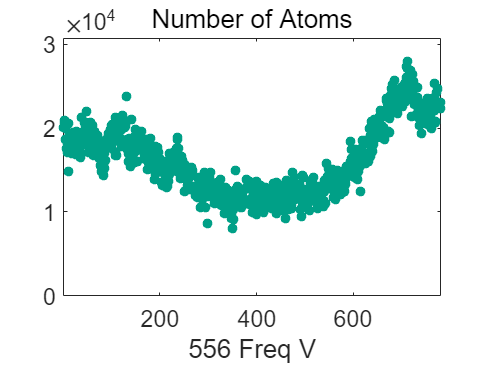

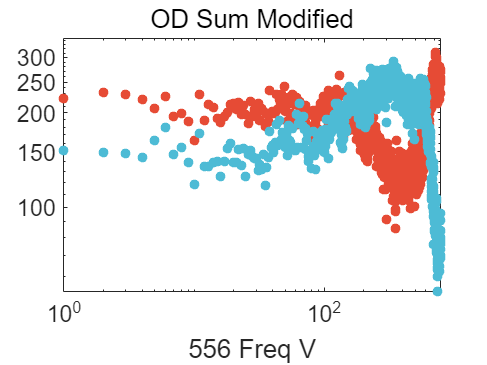

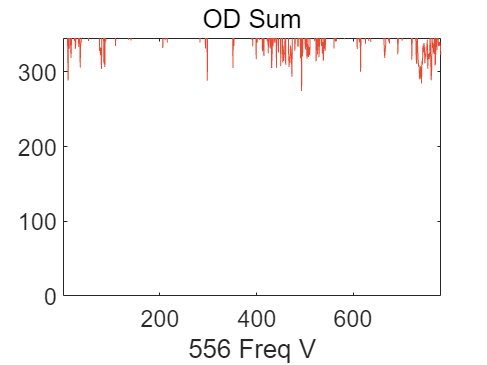

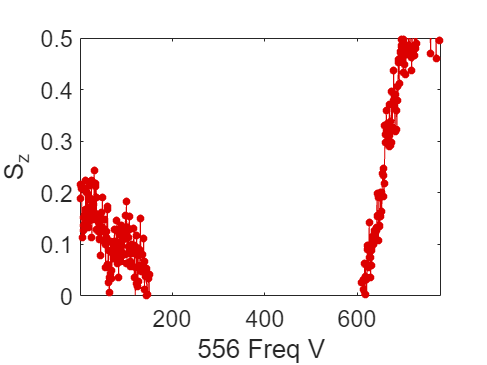

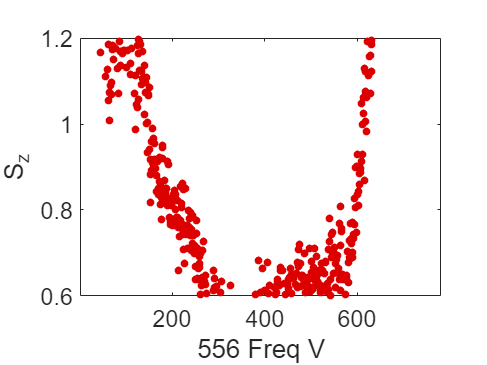

close all;
clear all;
maindir='\\Artemis-pc\e\Data\2023-11-14\Abs-1086\';
main_dir_0=maindir;
%load([maindir,'\result.mat']);

load([maindir,'\Fluctuation.mat']);


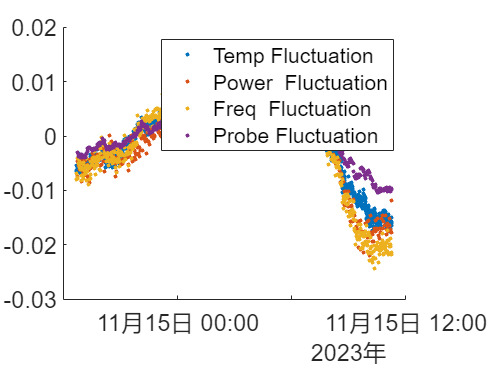


close all;

sz = (s1-s2)./(s1+s2);
dfreq = asin(sz)./(2*pi*550e-6);   % Hz
ratioFreq = dfreq./(1/251.6e-6);

%plot(ratioFreq);

temp = (temperature3-mean(temperature3))./temperature3;
AI = (Trigger_AI-mean(Trigger_AI))./(Trigger_AI+17e-3);
ratioProbe = (Photon-mean(Photon))./Photon;

f1 = figure;hold on;
l1 = plot(Time,temp,'.','MarkerSize',8);
l2 = plot(TimeAI,AI,'.','MarkerSize',8);
l3 = plot(Timelist,-ratioFreq./2,'.','MarkerSize',8);
l4 = plot(Time1,-ratioProbe./30,'.','MarkerSize',8);

legend('Temp Fluctuation','Power  Fluctuation','Freq  Fluctuation','Probe Fluctuation');

set(gca,'FontSize',16,'FontAngle','normal');


savefig(f1,[main_dir_0,'\Fluctuation.fig']);
saveas(f1,[main_dir_0,'\Fluctuation.png']);


save([main_dir_0,'\Fluctuation.mat']);
